a. 求频率响应H（jw）在频域画出幅值

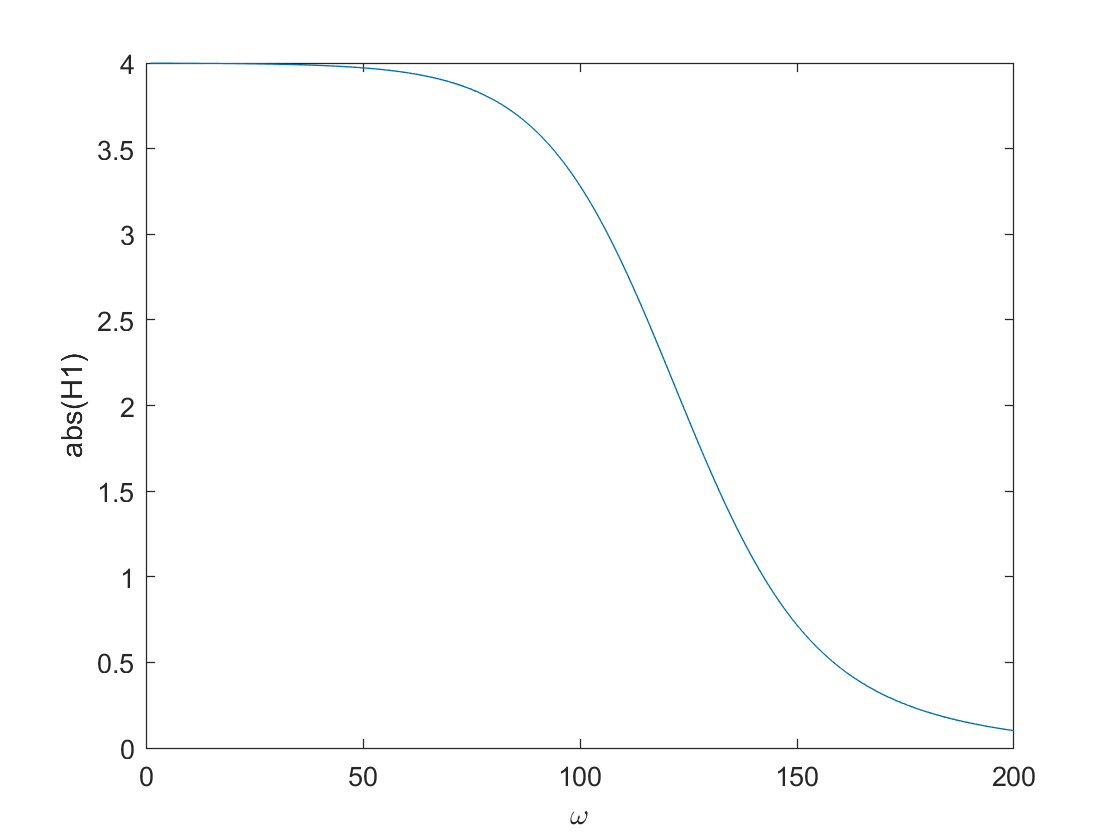

a1 = [1,3/2,1/2];
b1 = [1,-2];
H1 = freqs(b1,a1);
plot(abs(H1));
xlabel('\omega')
ylabel('abs(H1)');

b. 多项式分解

[r1,p1] = residue(b1,a1);
r1

r1 =      6
    -5


p1

p1 =    -1.0000
   -0.5000


因此H1 = 6/(jw+1)-5/(jw+0.5)

c.求h(t)然后画出来

x = 0:0.01:100

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


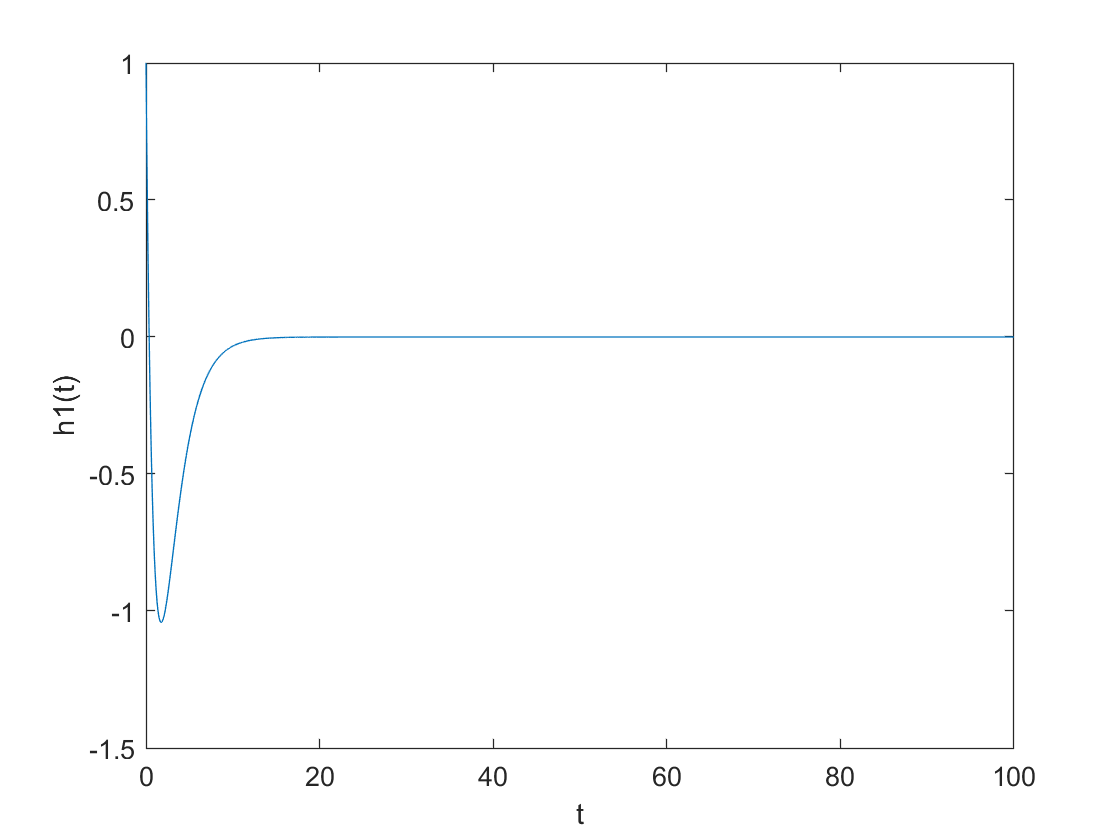

h1 = 6*exp(-x) - 5*exp(-0.5*x);
plot(x,h1)
xlabel('t')
ylabel('h1(t)');

d.求一个更复杂的微分方程的分子多项式和分母多项式的系数向量

a2 = [1 7 16 12];
b2 = [3 10 5];

e.分解（有重根）,写出分解后的表达式，同分之后的重组式

[r2 ,p2] = residue (b2 , a2)

r2 =     2.0000
    1.0000
   -3.0000


p2 =    -3.0000
   -2.0000
   -2.0000


f.求h2

x = 0:0.01:100

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


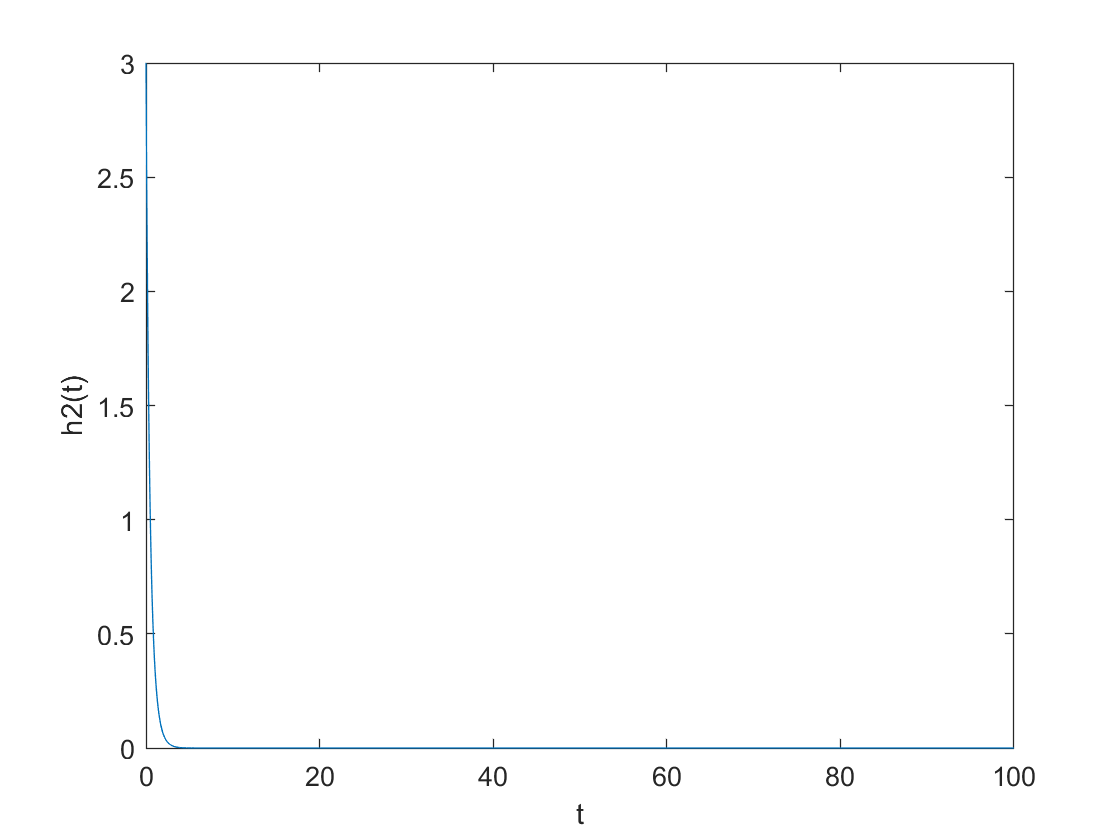

h2 = 2*exp(-3*x) + 1*exp(-2*x)+x.*exp(-2*x);
plot(x,h2)
xlabel('t')
ylabel('h2(t)');

g.系数向量

a3 = [1,0,-4];
b3 = [-4];

h.分解

[r3, p3] = residue(b3, a3)

r3 =     -1
     1


p3 =     2.0000
   -2.0000


i.求h3

x = -50:0.01:50

x =   -50.0000  -49.9900  -49.9800  -49.9700  -49.9600  -49.9500  -49.9400  -49.9300  -49.9200  -49.9100  -49.9000  -49.8900  -49.8800  -49.8700  -49.8600  -49.8500  -49.8400  -49.8300  -49.8200  -49.8100  -49.8000  -49.7900  -49.7800  -49.7700  -49.7600  -49.7500  -49.7400  -49.7300  -49.7200  -49.7100  -49.7000  -49.6900  -49.6800  -49.6700  -49.6600  -49.6500  -49.6400  -49.6300  -49.6200  -49.6100  -49.6000  -49.5900  -49.5800  -49.5700  -49.5600  -49.5500  -49.5400  -49.5300  -49.5200  -49.5100


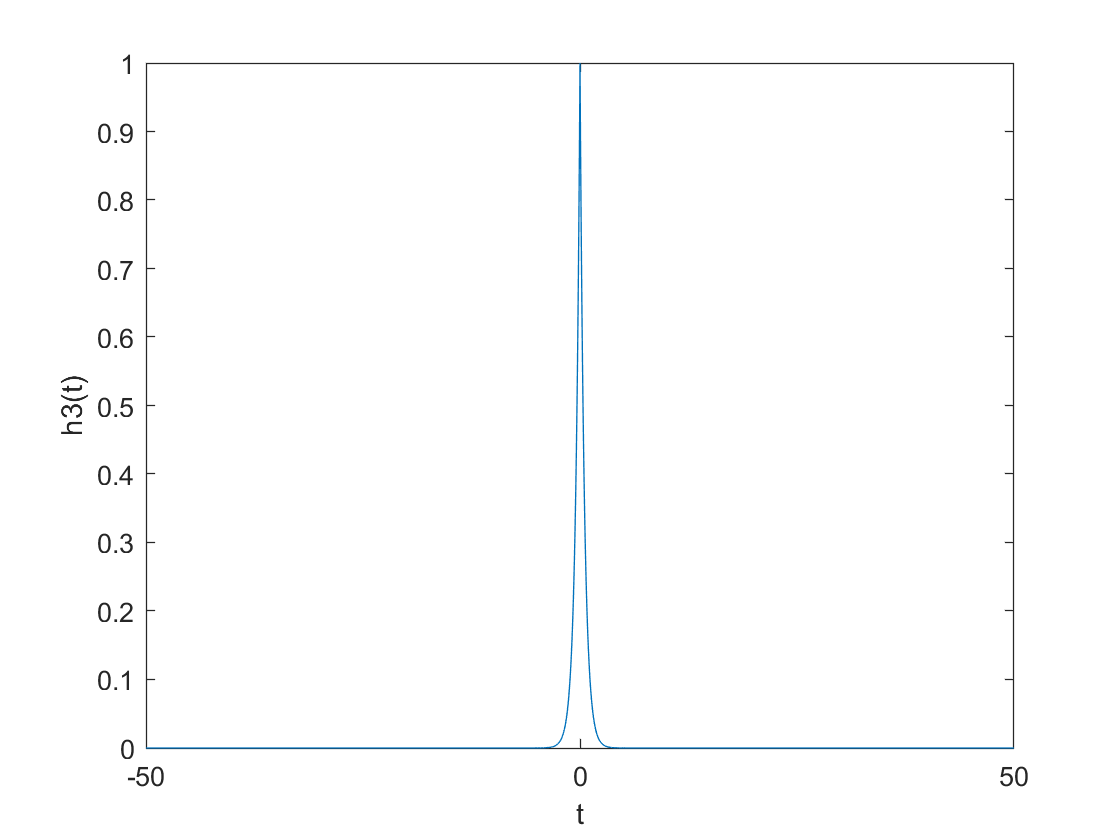

h3 =exp(-2*abs(x));
plot(x,h3)
xlabel('t')
ylabel('h3(t)');